# **MATLAB Assignment 3**

# Continuous and Discrete Wavelet Transforms 

**S.S. Hettiarachchi**

**180237G **

**BME**

## **1.3 Continuous Wavelet Decomposition**

close all; clc; clear;

s = 0.01:0.01:2; % Values of scaling factor
fs = 250; % Sample frequency
N = 3000; % Data length
t = (-N:N)/fs; % Time scale

%number of scalling factors
num_of_scal_fact = length(s); 

**Waveform generation **

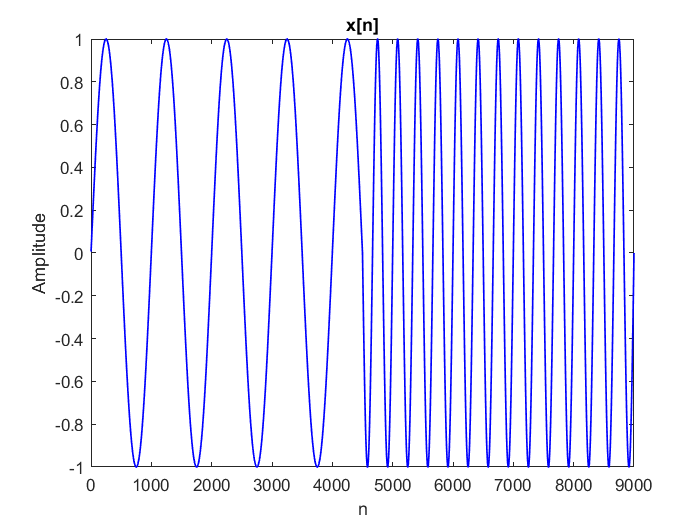

% time axises
n_1 = 1:1:(3*N/2) - 1;
n_2 = (3*N/2):1:3*N ; 

% Signal generation with two components
x = [sin(0.5*pi*n_1/fs) sin(1.5*pi*n_2/fs)];
n = [n_1 n_2];

figure('Name','x[n]')
plot(n, x, 'b','LineWidth',1);
title('x[n]'),xlabel('n'),ylabel('Amplitude');

**Continuous Wavelet Decomposition**

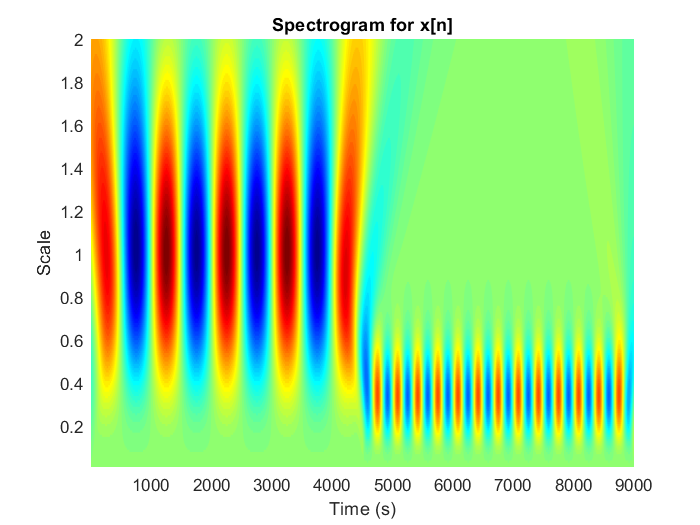

% By taking the tau parameter as zero

for i = 1:num_of_scal_fact
    
    % Defining the wavelet function (tau = 0)
    wavelet = (2/(sqrt(3*s(i))*(pi^(1/4))))*(1-(t/s(i)).^2).*exp(-((t/s(i)).^2) /2);
    
    % Convolution of x[n] signal and wavelet function
    conv_x = conv(x, wavelet, 'same'); 
    
    % Storing the coefficents
    cwt_coeff(i,:) = conv_x;
end

[~,max_coff_index] = max((cwt_coeff'),[],2);
max_coff_scalar = max_coff_index*0.01;

% Ploting the spectrogram
figure;
h = pcolor(n, s, cwt_coeff);
set(h, 'EdgeColor', 'none');
colormap jet
xlabel('Time (s)')
ylabel('Scale')
title('Spectrogram for x[n]')

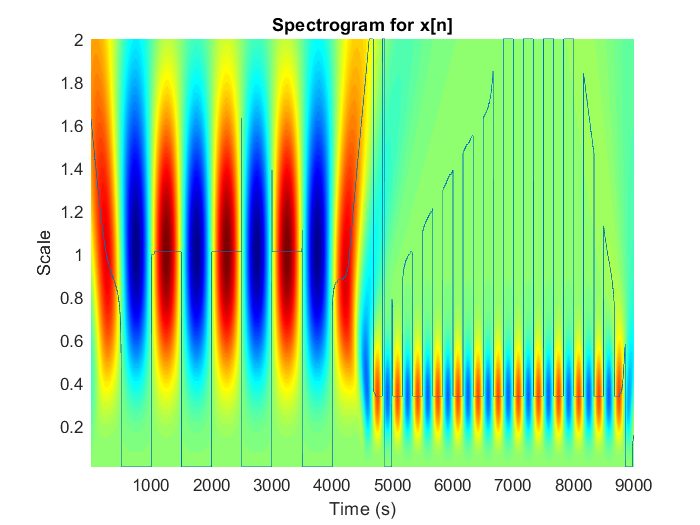

% maximum coefficient identification with a graph
hold on;
plot(n , max_coff_scalar);
hold off;

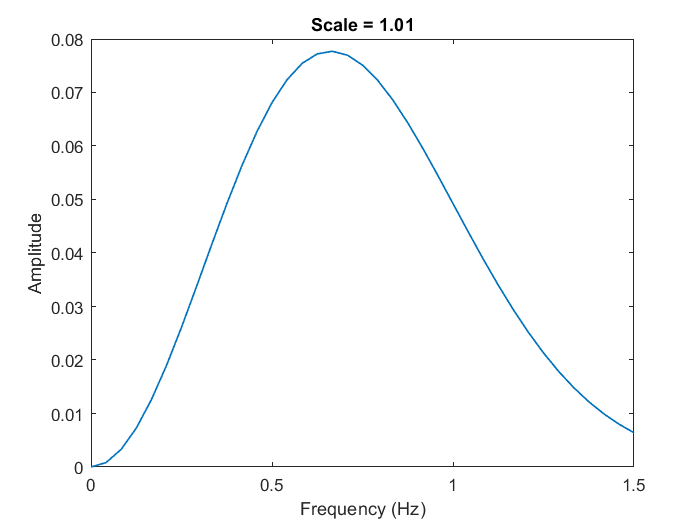

% plotting FFT of scalllignfactor  = 1.01 wavelet
figure;
wavelet_s_1 = (2/(sqrt(3*0.34)*(pi^(1/4))))*(1-(t/0.34).^2).*exp(-((t/0.34).^2) /2);

f_wavelt = fft(wavelet_s_1)/length(wavelet_s_1);

Hz = linspace(0,fs/2,floor(length(wavelet_s_1)/2)+1);

plot(Hz,2*abs(f_wavelt(1:length(Hz))), 'LineWidth',1);

title(['Scale = ', num2str(1.01)]), xlabel('Frequency (Hz)'), ylabel('Amplitude');
xlim([0 1.5]);